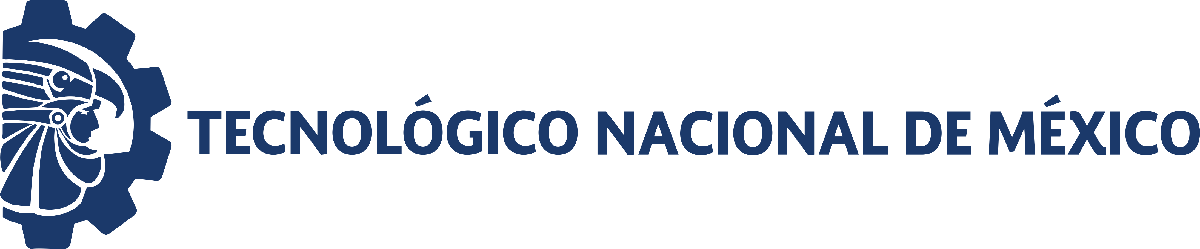                                 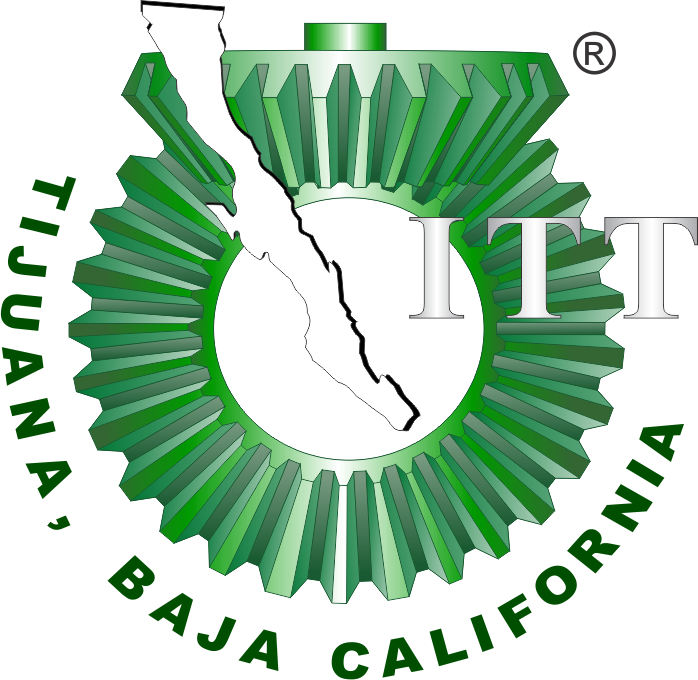

# Práctica 1: Leyes de crecimiento exponencial

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

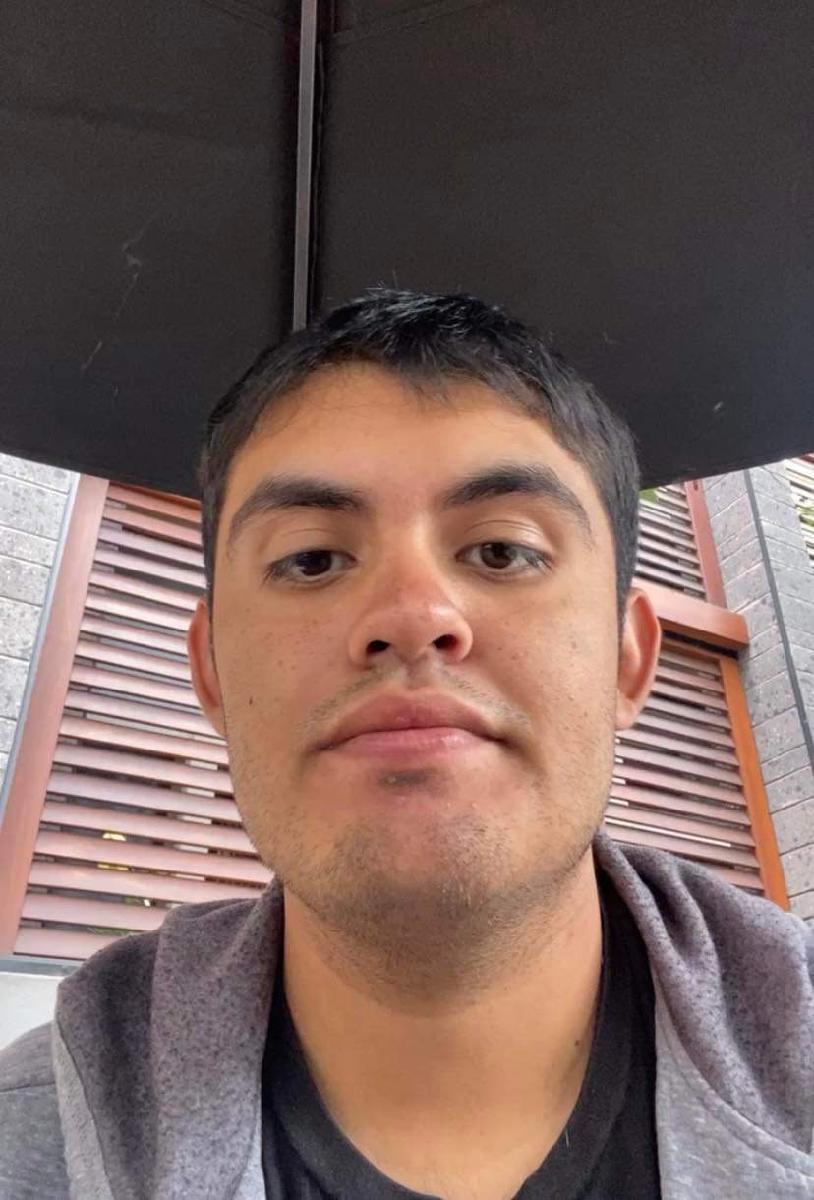

Nombre del alumno: **Andres Martin Bañuelos Elias**

Número de control: **21212142**

Correo institucional: **l21212142@tectijuana.edu.mx**

Carrera:** Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation Data

clc; clear; close all; warning('off','all')

## Exponential Growth


$$\dot{x} =\textrm{kx}$$


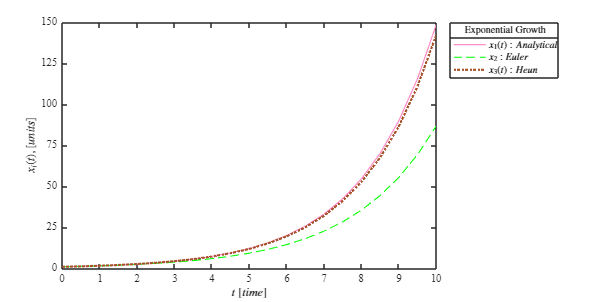

dt = 0.5; % integration step
x0 = 1; % initial condition
k_growth = 0.5; % parameter for growth
tend = 10; % simulation final time

% Simulate exponential growth
[t_growth, x1_growth, x2_growth, x3_growth] = sys_expgrowth(dt, x0, k_growth, tend);
% Plot growth
plot_results(t_growth, x1_growth, x2_growth, x3_growth, 'Exponential Growth');

## Exponential Decay


$$\dot{x} =-\textrm{kx}$$


Look for the point the plot where $x\left(t\right)=\frac{\textrm{x0}}{2}$ half life $\left(t_{\frac{1}{2}} \right)$ and compute the decay rate of the bioprocess, where $k=\frac{\textrm{ln2}}{t\;\frac{1}{2}}$

dt = 0.5; % integration step
x0 = 1; % initial condition
k_decay = -0.5; % parameter for decay
tend = 10; % simulation final time

% Simulate exponential decay
[t_decay, x1_decay, x2_decay, x3_decay] = sys_expgrowth(dt, x0, k_decay, tend);
% Plot decay
plot_results(t_decay, x1_decay, x2_decay, x3_decay, 'Exponential Decay');

% Find half-life
half_idx = find(x1_decay <= x0 / 2, 1); % index where x reaches half of x0
t_half = t_decay(half_idx); % half-life time

% Compute decay rate
k_computed = log(2) / t_half;

% Display results
disp(['Half-life time: ', num2str(t_half)]);

Half-life time: 1.5


disp(['Computed decay rate: ', num2str(k_computed)]);

Computed decay rate: 0.4621


% Plot decay
plot_results(t_decay, x1_decay, x2_decay, x3_decay, 'Exponential Decay');

%Functions for plots
function [t, x1, x2, x3] = sys_expgrowth(dt, x0, k, tend)
    t = (0:dt:tend)'; % time vector
    n = round(tend / dt);
    
    x2 = zeros(numel(t), 1); x2(1) = x0;
    x3 = zeros(numel(t), 1); x3(1) = x0;

    % Analytical solution
    x1 = x0 * exp(k * t);

    % Euler's method
    for i = 1:n
        x2(i+1) = x2(i) + (k * x2(i)) * dt;
    end

    % Heun's method
    for i = 1:n
        fx3 = k * x3(i);
        x3n = x3(i) + fx3 * dt;

        fx3n = k * x3n;
        x3(i+1) = x3(i) + (fx3 + fx3n) * dt / 2;
    end
end

function plot_results(t, x1, x2, x3, plot_title)
    set(figure, 'color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [2, 2, 20, 10]);
    set(gca, 'FontName', 'Times New Roman');
    fontsize(10, 'points');
    Mecambiareaindustrial = [
        1.00, 0.50, 0.75;  
        0.00, 1.00, 0.00;  
        0.65, 0.32, 0.17;  
        0.00, 0.50, 1.00;  
        0.85, 0.65, 0.13;  
        1.00, 0.75, 0.00;  
        0.60, 0.20, 0.80;  
        0.90, 0.90, 0.00;  
        0.00, 0.80, 0.20;  
        0.85, 0.35, 1.00;  
        0.00, 0.60, 0.55;  
        0.95, 0.25, 0.25   
    ];
    hold on; box on; grid off; colororder(Mecambiareaindustrial);
    %suffledcolors=Mecambiareaindustrial(randperm(size(Mecambiareaindustrial,1)),:);
    plot(t, x1, '-', 'LineWidth', 1);
    plot(t, x2, '--', 'LineWidth', 1);
    plot(t, x3, ':', 'LineWidth', 2);
    xlabel('$t$ $[time]$', 'Interpreter', 'latex');
    ylabel('$x_i(t), [{units}]$', 'Interpreter', 'latex');
    L = legend('$x_1(t):Analytical$', '$x_2:Euler$', '$x_3(t):Heun$');
    set(L, 'Interpreter', 'Latex', 'Location', 'NorthEastOutside');
    title(L, plot_title);
    xlim([0 10]); xticks(0:1:10);
    if strcmp(plot_title, 'Exponential Growth')
        ylim([0 150]); yticks(0:25:150);
    else
        ylim([0 1.1]); yticks(0:0.2:1);
    end
    exportgraphics(gcf, [plot_title, '.pdf'], 'ContentType', 'vector');
end

## First-order pharmacokinetics [modified exponential decay]: Controlled drug delivery by nanohydrogels


$$\dot{x} =\beta \left(1-e^{-\textrm{kt}} \right)$$


Reference: González‐Ayón, M. A., Sañudo‐Barajas, J. A., Picos‐Corrales, L. A., & Licea‐Claverie, A. (2015). PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil. *Journal of Polymer Science Part A: Polymer Chemistry*, *53*(22), 2662-2672.

## Experimental data

clc,clear; close all;
sys=readmatrix('data.csv');
t=round(sys(:,1));
x1=sys(:,2); x2=sys(:,3); x3=sys(:,4); x4=sys(:,5); 
T=array2table([t,x1,x2,x3,x4],'VariableNames',{'t [min]','N32','N35','N36','N45'}); disp(T)

    t [min]     N32      N35      N36      N45 
    _______    _____    _____    _____    _____

        0          0        0        0        0
       15      43.68    35.47    51.35    34.39
       30      64.31    55.89    69.07    49.08
       45       73.6    62.69    77.82    59.34
       60      80.95    70.15     84.3    68.31
       75      82.24    72.85     88.4    72.85
       91      85.59    75.44    92.07    76.74
      105       88.4    77.92    95.42    80.08
      120      90.56    78.03    97.15    83.65
      150      90.78    80.52    97.69    86.78
      180      90.24    80.73    97.69    88.83
      210       92.4     80.3    98.23    89.91



## Nonlinear regression and biostatistics

rho = [0.1, 100];
mdl_x1 = pharmacokinetics(t, x1, rho); y1 = mdl_x1.Fitted; %N32


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
-Student value: 2.2281
Adjusted R-squared: 0.9949
Corrected AIC (n/pars<40) : 53.1970
    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.040504    0.0017568    0.0039143    0.036589    0.044418    5.3239e-10
       beta         89.847      0.82673       1.8421      88.004      91.689    1.0668e-16



mdl_x2 = pharmacokinetics(t, x2, rho); y2 = mdl_x2.Fitted; %N35


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
-Student value: 2.2281
Adjusted R-squared: 0.9963
Corrected AIC (n/pars<40) : 46.5589
    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.037453    0.0013753    0.0030643    0.034388    0.040517    1.0315e-10
       beta         79.417      0.65053       1.4495      77.967      80.866    3.3367e-17



mdl_x3 = pharmacokinetics(t, x3, rho); y3 = mdl_x3.Fitted; %N36


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
-Student value: 2.2281
Adjusted R-squared: 0.9876
Corrected AIC (n/pars<40) : 65.0565
    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.041963    0.0028129    0.0062676    0.035695     0.04823     3.686e-08
       beta         95.959       1.3342       2.9728      92.986      98.932    6.5864e-15



mdl_x4 = pharmacokinetics(t, x4, rho); y4 = mdl_x4.Fitted; %N45


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
-Student value: 2.2281
Adjusted R-squared: 0.9903
Corrected AIC (n/pars<40) : 60.4553
    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.025988    0.0015189    0.0033843    0.022604    0.029373    9.8118e-09
       beta         87.728       1.4513       3.2337      84.494      90.962    3.7311e-14



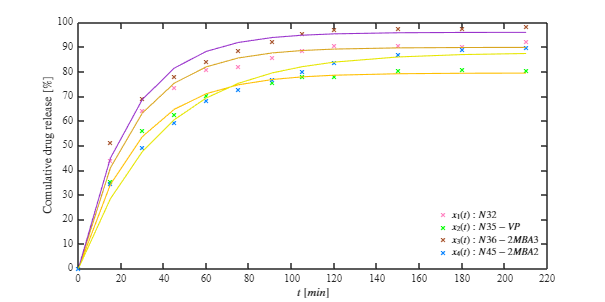

plotdata(t, x1, x2, x3, x4, y1, y2, y3, y4)

## Functions

function mdl = pharmacokinetics(to, xo, rho)
    model = @(rho, t) rho(2) * (1 - exp(-rho(1) * t)); 
    
    mdl = fitnlm(to, xo, model, rho);
    
    Estimate = table2array(mdl.Coefficients(:, 1));
    SE = table2array(mdl.Coefficients(:, 2));
    pvalue = table2array(mdl.Coefficients(:, 4));
    
    alpha = 0.05;
    CI95 = coefCI(mdl, alpha);
    dof = mdl.DFE;
    tval = tinv(1 - alpha / 2, dof);

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


x =          0
    2.9994
    5.9977
    8.9948
   11.9908
   14.9856
   17.9792
   20.9717
   23.9631
   26.9533


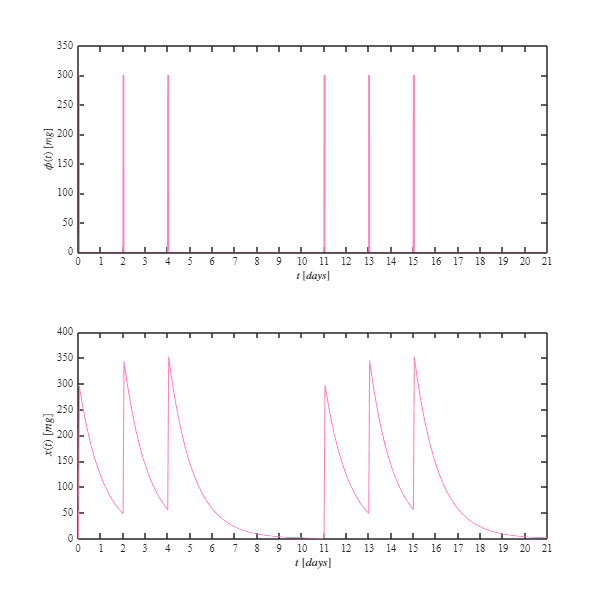

    MoE = SE * tval;

    
    Parameters = ['k   '; 'beta'];
    Results = table(Parameters, Estimate, SE, MoE, CI95, pvalue);
    
    fprintf('\nSample size (n): %d', numel(xo))
    fprintf('\nParameters to be estimated (pars): %d', numel(rho))
    fprintf('\nDegrees of freedom: %d', dof)
    fprintf('\nSignificance level (alpha): %.2f', alpha)
    fprintf('\n-Student value: %.4f', tval)
    fprintf('\nAdjusted R-squared: %.4f', mdl.Rsquared.Adjusted)
    fprintf('\nCorrected AIC (n/pars<40) : %.4f\n', mdl.ModelCriterion.AICc)
    
    disp(Results)
end


t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


x =          0
    2.9861
    5.9448
    8.8763
   11.7807
   14.6585
   17.5098
   20.3348
   23.1339
   25.9072


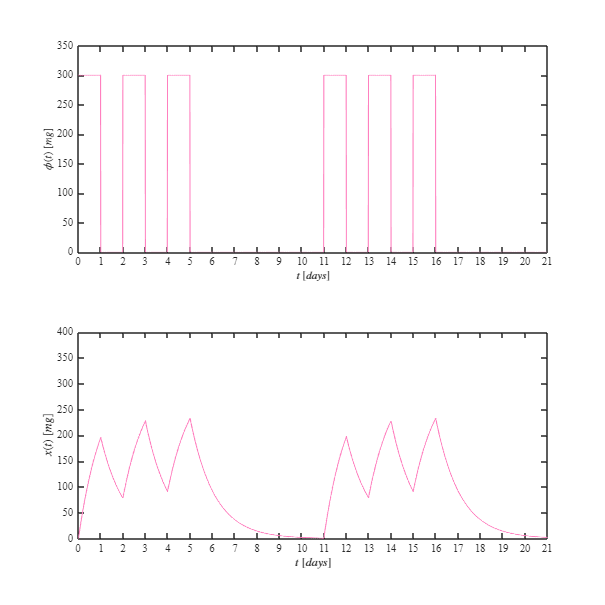

function plotdata(t, x1, x2, x3, x4, y1, y2, y3, y4)

set(figure(3),'color','w')
set(gcf,'units','Centimeters','Position',[2,2,20,10])
set(gca,'Fontname','Times New Roman')
fontsize(10,'points')
Mecambiareaindustrial = [
        1.00, 0.50, 0.75;  
        0.00, 1.00, 0.00;  
        0.65, 0.32, 0.17;  
        0.00, 0.50, 1.00;  
        0.85, 0.65, 0.13;  
        1.00, 0.75, 0.00;  
        0.60, 0.20, 0.80;  
        0.90, 0.90, 0.00;  
        0.00, 0.80, 0.20;  
        0.85, 0.35, 1.00;  
        0.00, 0.60, 0.55;  
        0.95, 0.25, 0.25   
    ];
hold on; box on; grid off,colororder(Mecambiareaindustrial)

%Experimental data
plot(t,x1,'x','MarkerSize',5,'LineWidth',1)
plot(t,x2,'x','MarkerSize',5,'LineWidth',1)
plot(t,x3,'x','MarkerSize',5,'LineWidth',1)
plot(t,x4,'x','MarkerSize',5,'LineWidth',1)

%Fitted values
plot(t,y1,'-','LineWidth',1)
plot(t,y2,'-','LineWidth',1)
plot(t,y3,'-','LineWidth',1)
plot(t,y4,'-','LineWidth',1)

xlabel('$t$ $[min]$','Interpreter','latex')
ylabel('Comulative drug release $[\%$]','Interpreter','latex')
xlim([0 220]); xticks(0:20:220)
ylim([0 100]); yticks(0:10:100)
L = legend('$x_1(t):N32$', '$x_2(t):N35-VP$', '$x_3(t):N36-2MBA3$', '$x_4(t):N45-2MBA2$', ...
    'Interpreter', 'latex', 'Location', 'SouthEast', 'Box', 'off');

%Exportgraphics nanohydrogels
exportgraphics(gcf,'nanohydrogels.pdf','ContentType','Vector')
exportgraphics(gcf,'nanohydrogels.png','Resolution',600)
print('nanohydrogels', '-dsvg')
print('nanohydrogels', '-depsc')

end

## Chemotherapy dynamics in the blood compartment

Assume that the chemotherapy drug within the blood compartment follows first-order kinetics. Let us apply modified exponential decay to illustrate the dynamics of this drug when administered with the following scheme:

- **Protocol**: (3 imatinib intakes every 2 days + 7 days of rest)*2 cycles.

- **Dosing:** 300 mg/day per dose.

- **Application frecuency: **One dose every 2 days.

- **Doses per cycle:** 3 doses.

- **Numer of cycles:** 2 cycles.

- **Imatinib biological half life **[$T_{\frac{1}{2}}$]: 18 hours [0.75 days]. Reference: [https://go.drugbank.com/drugs/DB00619](https://go.drugbank.com/drugs/DB00619)

- **ODE:** $\overset{\ldotp }{X} =\phi \left(t\right)-\mu x$

## Time: Hours

dt = 0.01; dose = 300; mu = log(2)/18 ; tend = 21*24;
phi = zeros (tend/dt+1,1);
%Cycle1
phi(1:1/dt) = dose;
phi(2*24/dt:(2*24+1)/dt) = dose;
phi(4*24/dt:(4*24+1)/dt) = dose;

% Cycle 2
phi(11*24/dt:(11*24+1)/dt) = dose;
phi(13*24/dt:(13*24+1)/dt) = dose;
phi(15*24/dt:(15*24+1)/dt) = dose;

[t,x] = sys_chemo(dt,mu,phi,tend)
plotchemo(t/24,phi,x,'hours')

## Time:Days

dt = 0.01; dose = 300; mu = log(2)/(18/24) ; tend = 24;
phi = zeros (tend/dt+1,1);

%Cycle1
phi(1:1/dt) = dose;
phi(2/dt:3/dt) = dose;
phi(4/dt:5/dt) = dose;

%Cycle1
phi(11/dt:12/dt) = dose;
phi(13/dt:14/dt) = dose;
phi(15/dt:16/dt) = dose;

[t,x] = sys_chemo(dt,mu,phi,tend)
plotchemo(t,phi,x,'days')

## Functions

function [t,x] = sys_chemo(dt,mu,phi,tend)
    t = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros (numel(t),1);

    %Heun's method
    for i = 1:n
       [fx] = f(x(i),phi(i));
       xn = x(i) + fx*dt;
       [fxn] = f(xn,phi(i));

       x(i+1) = x(i) + (fx + fxn)*dt/2;
    end
    function [dx] = f(x,phi)
       dx = phi - mu*x;
    end
end


function plotchemo(t,phi,x,time)
set (figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,20])

    subplot(2,1,1)
    set(gca,'FontName','Times New Roman')
    fontsize ( 10,'points')
 hold on; box on; grid off; 
   plot(t,phi,'-','LineWidth',1,'Color',[1.00, 0.50, 0.75])
   %Legends
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$\phi(t)$ $[mg]$','Interpreter','latex')
    xlim([0 21]); xticks(0:1:21)
    ylim([0 350]); yticks(0:50:350)

     subplot(2,1,2)

    set(gca,'FontName','Times New Roman')
    fontsize ( 10,'points')
 hold on; box on; grid off; 
   plot(t,x,'-','LineWidth',1,'Color',[1.00, 0.50, 0.75])
   %Legends
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x(t)$ $[mg]$','Interpreter','latex')
    xlim([0 21]); xticks(0:1:21)
    ylim([0 400]); yticks(0:50:400)


  exportgraphics(gcf,['Chemo',time,' .pdf'],'ContentType','vector')
end
